run AircraftData.mlx

Vanguard = struct with fields:
              MTOW: 147661
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147661
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147661
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147661
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]



%Flight Conditions
V = 375; %kts 
h = 25000; %ft
DynVisc = 3.2166*10^(-7); %Slug/ft-s CHANGES WITH ALT
MTOW = Vanguard.MTOW;
W = MTOW*0.946;

[TempRat, PresRat, DensRat, SpeedSound] = ISA(h);
V=V*1.688;
M = V/SpeedSound;

%Airfoil Parameters
Cla = 2*pi;
Tmax = Vanguard.Wing.Airfoil.TMax;
LocMaxT = Vanguard.Wing.Airfoil.LocTMax;
PerLamFlow = Vanguard.Wing.Airfoil.PerLamFlow;
CLDMin = Vanguard.Wing.Airfoil.CldMin;

%Planform Parameters
S = Vanguard.Wing.S; %ft^2
b = Vanguard.Wing.b;
AR = Vanguard.Wing.AR;
TaperRatio = Vanguard.Wing.TaperRatio;
Q = 1.01;
SweepQuartC = Vanguard.Wing.QuarterChordSweep;

%Fuselage Parameters
Df = Vanguard.Fuselage.Diameter; %ft
LNose = Vanguard.Fuselage.NoseLength; %ft
LMid = Vanguard.Fuselage.CargoLength; %ft
LTail = Vanguard.Fuselage.TailLength; %ft
DBase = Vanguard.Fuselage.BaseDia; %ft
ABase = Vanguard.Fuselage.ABase;
UpsweepAngle = Vanguard.Fuselage.UpsweepAngle; %rad

%Vertical Tail Parameters NOTE: Half Wing
Sv = Vanguard.VerticalTail.S; %ft^2
ARv = Vanguard.VerticalTail.AR;
TaperRatiov = Vanguard.VerticalTail.TaperRatio;
bv = Vanguard.VerticalTail.b;
QVt = 1.05;
LocMaxTv = Vanguard.VerticalTail.LocTMax;
Tmaxv = Vanguard.VerticalTail.TMax;

%Horizontal Tail Parameters
Sh = Vanguard.HorizontalTail.S; %ft^2
ARh = Vanguard.HorizontalTail.AR;
TaperRatioh = Vanguard.HorizontalTail.TaperRatio;
bh = Vanguard.HorizontalTail.b;
QHt = 1.05;
LocMaxTh = Vanguard.HorizontalTail.LocTMax;
Tmaxh = Vanguard.HorizontalTail.TMax;

%Nacelle Parameters
LNacelle = 9.3;
DNacelle = 5.2;

%Blister Parameters
LBlister = 16;
DBlister = 3;

%Induced Drag Factor

Ne = 0; %Num of engines ON TOP of Wing
TaperFunc = 0.005*(1+1.5*(TaperRatio-0.6)^2);
K = (1+(0.142+TaperFunc*AR*(10*Tmax)^(0.33))/(cosd(SweepQuartC)^2)+(0.1*(3*Ne+1))/((4+AR)^0.8))*(1+0.12*M^6)/(pi*AR);
e = 1/(K*AR*pi);

%Total Zero-lift Drag

[CDoWing] = WingZeroLiftDrag(V,Q,TaperRatio,DynVisc,0,S,AR,b,h,LocMaxT,Df,PerLamFlow,Tmax);

Vanguard = struct with fields:
           MTOW: 147661
    WingLoading: 93.5500
           Wing: [1×1 struct]


Vanguard = struct with fields:
           MTOW: 147661
    WingLoading: 93.5500
           Wing: [1×1 struct]


Vanguard = struct with fields:
           MTOW: 147661
    WingLoading: 93.5500
           Wing: [1×1 struct]


Vanguard = struct with fields:
           MTOW: 147661
    WingLoading: 93.5500
           Wing: [1×1 struct]


V = 1.0685e+03

M = 1.0521

Cr = 16.6852

Cmac = 13.8491

Ymac = 25.2857

SweepMaxT = -1.6697

Vanguard = struct with fields:
           MTOW: 147661
    WingLoading: 93.5500
           Wing: [1×1 struct]


Vanguard = struct with fields:
           MTOW: 147661
    WingLoading: 93.5500
           Wing: [1×1 struct]


Vanguard = struct with fields:
           MTOW: 147661
    WingLoading: 93.5500
           Wing: [1×1 struct]


Vanguard = struct with fields:
           MTOW: 147661
    WingLoading: 93.5500
           Wing: [1×1 struct]


Re = 8.2623e+07

SweepMaxT = -1.6697

Cf = 0.0021

FF = 1.7248

Swet = 2.7008e+03

CDo = 0.0064


[CDoHt] = WingZeroLiftDrag(V,QHt,TaperRatioh,DynVisc,0,Sh,ARh,bh,h,LocMaxTh,0,PerLamFlow,Tmaxh);

Vanguard = struct with fields:
           MTOW: 147661
    WingLoading: 93.5500
           Wing: [1×1 struct]


Vanguard = struct with fields:
           MTOW: 147661
    WingLoading: 93.5500
           Wing: [1×1 struct]


Vanguard = struct with fields:
           MTOW: 147661
    WingLoading: 93.5500
           Wing: [1×1 struct]


Vanguard = struct with fields:
           MTOW: 147661
    WingLoading: 93.5500
           Wing: [1×1 struct]


V = 1.0685e+03

M = 1.0521

Cr = 16.6852

Cmac = 13.8491

Ymac = 9.5530

SweepMaxT = -1.6531

Vanguard = struct with fields:
           MTOW: 147661
    WingLoading: 93.5500
           Wing: [1×1 struct]


Vanguard = struct with fields:
           MTOW: 147661
    WingLoading: 93.5500
           Wing: [1×1 struct]


Vanguard = struct with fields:
           MTOW: 147661
    WingLoading: 93.5500
           Wing: [1×1 struct]


Vanguard = struct with fields:
           MTOW: 147661
    WingLoading: 93.5500
           Wing: [1×1 struct]


Re = 8.2623e+07

SweepMaxT = -1.6531

Cf = 0.0021

FF = 1.6583

Swet = 815.7600

CDo = 0.0076


CDoHt = CDoHt*Sh/S

CDoHt = 0.0019


[CDoVt] = WingZeroLiftDrag(V,QVt,TaperRatiov,DynVisc,0,Sv,ARv,bv,h,LocMaxTv,0,PerLamFlow,Tmaxv);

Vanguard = struct with fields:
           MTOW: 147661
    WingLoading: 93.5500
           Wing: [1×1 struct]


Vanguard = struct with fields:
           MTOW: 147661
    WingLoading: 93.5500
           Wing: [1×1 struct]


Vanguard = struct with fields:
           MTOW: 147661
    WingLoading: 93.5500
           Wing: [1×1 struct]


Vanguard = struct with fields:
           MTOW: 147661
    WingLoading: 93.5500
           Wing: [1×1 struct]


V = 1.0685e+03

M = 1.0521

Cr = 16.6852

Cmac = 13.8491

Ymac = 10.3920

SweepMaxT = -1.8842

Vanguard = struct with fields:
           MTOW: 147661
    WingLoading: 93.5500
           Wing: [1×1 struct]


Vanguard = struct with fields:
           MTOW: 147661
    WingLoading: 93.5500
           Wing: [1×1 struct]


Vanguard = struct with fields:
           MTOW: 147661
    WingLoading: 93.5500
           Wing: [1×1 struct]


Vanguard = struct with fields:
           MTOW: 147661
    WingLoading: 93.5500
           Wing: [1×1 struct]


Re = 8.2623e+07

SweepMaxT = -1.8842

Cf = 0.0021

FF = 1.6583

Swet = 1.2236e+03

CDo = 0.0076


CDoVt = CDoVt*Sv/S/2

CDoVt = 0.0014


[CDoFuse] = 0.0066 %ParaDragFuse(h,V,LMid,LNose,LTail,Df,DynVisc,S)

CDoFuse = 0.0066


[CDoNacelle] = 4*ParaDragNacelle(h,V,LNacelle,DNacelle,DynVisc,S)

Re = 3.2869e+07

Cf = 0.0023

FF = 1.1957

SWet = 151.9274

CDo = 3.9363e-04

CDoNacelle = 0.0016


[CDoBlisters] = ParaDragNacelle(h,V,LBlister,DBlister,DynVisc,S)

Re = 5.6549e+07

Cf = 0.0021

FF = 1.0656

SWet = 150.7964

CDo = 3.1999e-04

CDoBlisters = 3.1999e-04


UpSweepDrag = 3.83*UpsweepAngle^2.5*pi*Df^2/4/S

UpSweepDrag = 0.0038


CDoCamber = e/(1-e)*K*CLDMin^2

CDoCamber = 0.0020


BaseDrag = (0.1+0.1222*M^8)*ABase/S

BaseDrag = 8.1830e-04


CDoTotal = CDoWing + CDoHt + CDoVt + CDoFuse + UpSweepDrag + BaseDrag + CDoNacelle + CDoCamber

CDoTotal = 0.0245





CL = -0.5:0.01:1.5

CL =    -0.5000   -0.4900   -0.4800   -0.4700   -0.4600   -0.4500   -0.4400   -0.4300   -0.4200   -0.4100   -0.4000   -0.3900   -0.3800   -0.3700   -0.3600   -0.3500   -0.3400   -0.3300   -0.3200   -0.3100   -0.3000   -0.2900   -0.2800   -0.2700   -0.2600   -0.2500   -0.2400   -0.2300   -0.2200   -0.2100   -0.2000   -0.1900   -0.1800   -0.1700   -0.1600   -0.1500   -0.1400   -0.1300   -0.1200   -0.1100   -0.1000   -0.0900   -0.0800   -0.0700   -0.0600   -0.0500   -0.0400   -0.0300   -0.0200   -0.0100



LDMax = 0;

for x=1:201
    
   CD(x) = CDoTotal + K*CL(x)^2;
   
   if CL(x)/CD(x)>LDMax
       
       LDMax = CL(x)/CD(x)
       
   end
   
end

LDMax = 0.4075

LDMax = 0.8146

LDMax = 1.2208

LDMax = 1.6257

LDMax = 2.0288

LDMax = 2.4298

LDMax = 2.8283

LDMax = 3.2237

LDMax = 3.6158

LDMax = 4.0041

LDMax = 4.3883

LDMax = 4.7681

LDMax = 5.1430

LDMax = 5.5127

LDMax = 5.8770

LDMax = 6.2356

LDMax = 6.5881

LDMax = 6.9343

LDMax = 7.2740

LDMax = 7.6070

LDMax = 7.9330

LDMax = 8.2519

LDMax = 8.5636

LDMax = 8.8677

LDMax = 9.1644

LDMax = 9.4533

LDMax = 9.7346

LDMax = 10.0080

LDMax = 10.2735

LDMax = 10.5311

LDMax = 10.7807

LDMax = 11.0225

LDMax = 11.2563

LDMax = 11.4821

LDMax = 11.7001

LDMax = 11.9103

LDMax = 12.1127

LDMax = 12.3073

LDMax = 12.4944

LDMax = 12.6739

LDMax = 12.8460

LDMax = 13.0107

LDMax = 13.1682

LDMax = 13.3187

LDMax = 13.4621

LDMax = 13.5987

LDMax = 13.7286

LDMax = 13.8519

LDMax = 13.9688

LDMax = 14.0794

LDMax = 14.1838

LDMax = 14.2823

LDMax = 14.3749

LDMax = 14.4618

LDMax = 14.5432

LDMax = 14.6192

LDMax = 14.6900

LDMax = 14.7557

LDMax = 14.8164

LDMax = 14.8724

LDMax = 14.9237

LDMax = 14.9706

LDMax = 15.0130

LDMax = 15.0513

LDMax = 15.0855

LDMax = 15.1158

LDMax = 15.1423

LDMax = 15.1651

LDMax = 15.1844

LDMax = 15.2003

LDMax = 15.2129

LDMax = 15.2224

LDMax = 15.2288

LDMax = 15.2323

LDMax = 15.2330


Line1 = [0]

Line1 = 0


% K2 = 1/(0.987*pi*AR)
% 
% LDMax2 = 0;
% 
% for x=1:201
%     
%    CD2(x) = CDoTotal2 + K2*CL(x)^2;
%    
%    if CL(x)/CD(x)>LDMax2
%        
%        LDMax2 = CL(x)/CD2(x)
%        
%    end
%    
% end

plot (CD,CL)

xlabel('Drag Coefficient, {\it C_{D}}')
ylabel('Lift Coefficient, {\it C_{L}}')
grid on
grid minor
hold on
ax = gca;
ax.XLim = [0 0.1152]

ax =   Axes with properties:

             XLim: [0 0.1152]
             YLim: [-0.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1163 0.7750 0.8087]
            Units: 'normalized'

  Show all properties


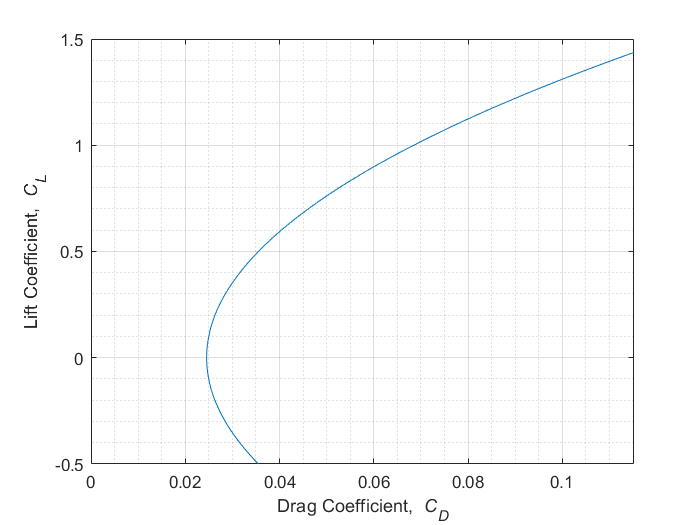

%ax.XAxisLocation = 'origin';
hold off

LDMax

LDMax = 15.2330


DynViscSL = 3.737*10^(-7)

DynViscSL = 3.7370e-07

Swf = 1100

Swf = 1100

%%%%%%%%%%%%%%%%%%%%%
% Landing and Takeoff
%%%%%%%%%%%%%%%%%%%%%

[CDoWingSL] = WingZeroLiftDrag(100,Q,TaperRatio,DynViscSL,0,S,AR,b,0,LocMaxT,Df,PerLamFlow,Tmax);

Vanguard = struct with fields:
           MTOW: 147661
    WingLoading: 93.5500
           Wing: [1×1 struct]


Vanguard = struct with fields:
           MTOW: 147661
    WingLoading: 93.5500
           Wing: [1×1 struct]


Vanguard = struct with fields:
           MTOW: 147661
    WingLoading: 93.5500
           Wing: [1×1 struct]


Vanguard = struct with fields:
           MTOW: 147661
    WingLoading: 93.5500
           Wing: [1×1 struct]


V = 168.8000

M = 0.1513

Cr = 16.6852

Cmac = 13.8491

Ymac = 25.2857

SweepMaxT = -1.6697

Vanguard = struct with fields:
           MTOW: 147661
    WingLoading: 93.5500
           Wing: [1×1 struct]


Vanguard = struct with fields:
           MTOW: 147661
    WingLoading: 93.5500
           Wing: [1×1 struct]


Vanguard = struct with fields:
           MTOW: 147661
    WingLoading: 93.5500
           Wing: [1×1 struct]


Vanguard = struct with fields:
           MTOW: 147661
    WingLoading: 93.5500
           Wing: [1×1 struct]


Re = 2.5099e+07

SweepMaxT = -1.6697

Cf = 0.0024

FF = 1.2165

Swet = 2.7008e+03

CDo = 0.0050


[CDoHtSL] = WingZeroLiftDrag(100,QHt,TaperRatioh,DynViscSL,0,Sh,ARh,bh,0,LocMaxTh,0,PerLamFlow,Tmaxh);

Vanguard = struct with fields:
           MTOW: 147661
    WingLoading: 93.5500
           Wing: [1×1 struct]


Vanguard = struct with fields:
           MTOW: 147661
    WingLoading: 93.5500
           Wing: [1×1 struct]


Vanguard = struct with fields:
           MTOW: 147661
    WingLoading: 93.5500
           Wing: [1×1 struct]


Vanguard = struct with fields:
           MTOW: 147661
    WingLoading: 93.5500
           Wing: [1×1 struct]


V = 168.8000

M = 0.1513

Cr = 16.6852

Cmac = 13.8491

Ymac = 9.5530

SweepMaxT = -1.6531

Vanguard = struct with fields:
           MTOW: 147661
    WingLoading: 93.5500
           Wing: [1×1 struct]


Vanguard = struct with fields:
           MTOW: 147661
    WingLoading: 93.5500
           Wing: [1×1 struct]


Vanguard = struct with fields:
           MTOW: 147661
    WingLoading: 93.5500
           Wing: [1×1 struct]


Vanguard = struct with fields:
           MTOW: 147661
    WingLoading: 93.5500
           Wing: [1×1 struct]


Re = 2.5099e+07

SweepMaxT = -1.6531

Cf = 0.0024

FF = 1.1696

Swet = 815.7600

CDo = 0.0059


CDoHtSL = CDoHtSL*Sh/S

CDoHtSL = 0.0015


[CDoVtSL] = WingZeroLiftDrag(100,QVt,TaperRatiov,DynViscSL,0,Sv,ARv,bv,0,LocMaxTv,0,PerLamFlow,Tmaxv);

Vanguard = struct with fields:
           MTOW: 147661
    WingLoading: 93.5500
           Wing: [1×1 struct]


Vanguard = struct with fields:
           MTOW: 147661
    WingLoading: 93.5500
           Wing: [1×1 struct]


Vanguard = struct with fields:
           MTOW: 147661
    WingLoading: 93.5500
           Wing: [1×1 struct]


Vanguard = struct with fields:
           MTOW: 147661
    WingLoading: 93.5500
           Wing: [1×1 struct]


V = 168.8000

M = 0.1513

Cr = 16.6852

Cmac = 13.8491

Ymac = 10.3920

SweepMaxT = -1.8842

Vanguard = struct with fields:
           MTOW: 147661
    WingLoading: 93.5500
           Wing: [1×1 struct]


Vanguard = struct with fields:
           MTOW: 147661
    WingLoading: 93.5500
           Wing: [1×1 struct]


Vanguard = struct with fields:
           MTOW: 147661
    WingLoading: 93.5500
           Wing: [1×1 struct]


Vanguard = struct with fields:
           MTOW: 147661
    WingLoading: 93.5500
           Wing: [1×1 struct]


Re = 2.5099e+07

SweepMaxT = -1.8842

Cf = 0.0024

FF = 1.1696

Swet = 1.2236e+03

CDo = 0.0059


CDoVtSL = CDoVtSL*Sv/S/2;

[CDoFuseSL] = ParaDragFuse(0,100,LMid,LNose,LTail,Df,DynViscSL,S);

Cf = 0.0021

FF = 1.2392

SWet = 4.2990e+03

CDo = 0.0071


[CDoNacelleSL] = 4*ParaDragNacelle(0,100,LNacelle,DNacelle,DynViscSL,S);

Re = 9.9849e+06

Cf = 0.0027

FF = 1.1957

SWet = 151.9274

CDo = 4.7306e-04


[CDoBlistersSL] = ParaDragNacelle(0,100,LBlister,DBlister,DynViscSL,S);

Re = 1.7178e+07

Cf = 0.0025

FF = 1.0656

SWet = 150.7964

CDo = 3.8320e-04

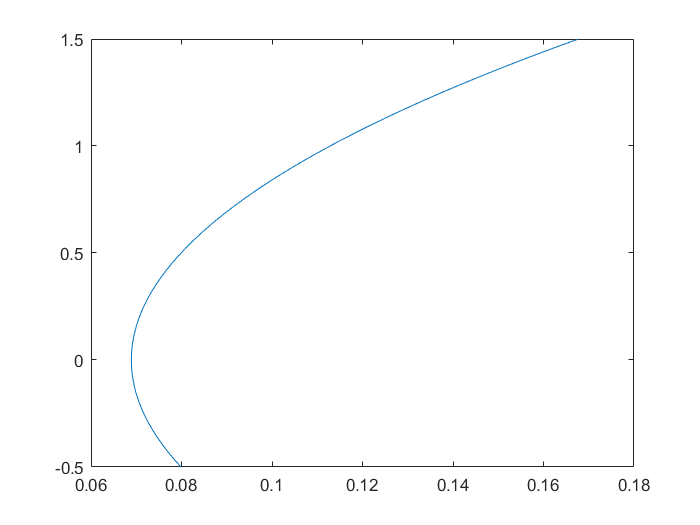


CDo_CleanSL = CDoWingSL + CDoHtSL + CDoVtSL + CDoFuseSL + UpSweepDrag + BaseDrag + CDoNacelleSL + CDoCamber;

k1 = 1.75;

k2Landing = 0.0375;

k2TO = 0.0125;

dCDoLanding = k1*k2Landing*Swf/S;

dCDoTO = k1*k2TO*Swf/S;

for x=1:201
    
   CDLanding(x) = CDo_CleanSL+dCDoLanding + K*CL(x)^2;

   CDTO(x) = CDo_CleanSL+dCDoTO + K*CL(x)^2;
    
end



plot (CDLanding,CL)

plot (CDTO,CL)

legend('Cruise','Landing', 'Takeoff')

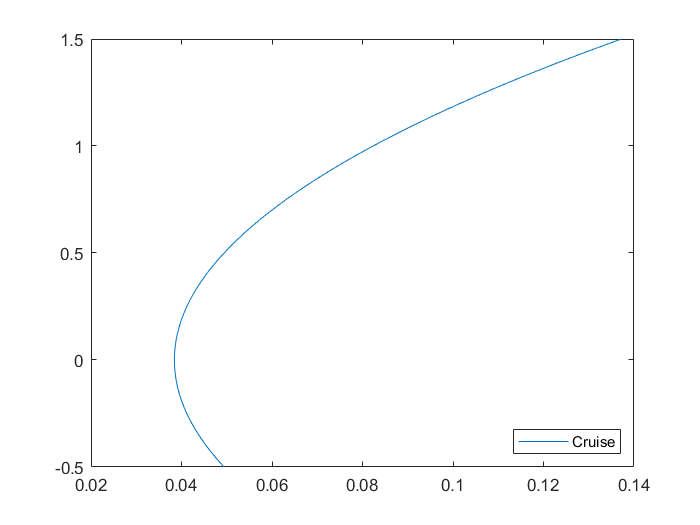

legend('Location','southeast')

hold off